# 'lathe' method usage example

#### Common setup for all examples

ex_setup

Setup complete


#### Start timer

tic

#### Povlab object

pl = povlab( povray_version,...
             povray_path, ...
             povray_out_dir);

#### Scene

pl.scene_begin('scene_file', 'lathe.pov', 'image_file', 'lathe.png');
    pl.include("shapes");
    pl.include("glass");
    
    pl.global_settings("assumed_gamma 1");
    
    % Camera
    pl.camera('angle', 33, 'location', [23 7 7], 'look_at', [0 4 1.5], 'type', 'perspective');
    
    % Light
    pl.light('location', [23 6 11], 'color', [0.6 0.6 0.6]);
    
    % Floor
    tex = pl.declare("tex", pl.texture('pigment_odd', [4 4 4], 'pigment_even', [0 0 0], 'finish', "phong 1 reflection {0.4 metallic 0.2}"));
    pl.plane('normal', [0,0,1], 'distance', 0, 'texture', tex,  'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);    
    
    % Limit
    tex_gray = pl.declare("tex_gray", pl.texture('pigment', [0.4 0.4 0.4], 'finish', "phong 1 reflection {0.4 metallic 0.2}"));
    pl.plane('normal', [1,0,1], 'distance', -20, 'texture', tex_gray,  'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
    
    % Bottle 1
    pl.lathe('points', [0.00 0.00; 0.35 0.00; 0.62 0.54; 0.21 0.83; 0.19 1.46; 0.29 1.50; 0.26 1.53],...
            'spline_type', 'quadratic_spline',...
            'sturm', true,...
            'texture', 'Dark_Green_Glass',...
            'scale', [4 4 4], 'rotate', [ 90 0 0], 'translate', [6 2.8 0]);
    
    % Bottle 2
    pl.lathe('points', [0.00 0.00; 0.36 0.00; 0.62 0.54; 0.21 0.83; 0.19 1.46; 0.29 1.50; 0.26 1.53],...
            'spline_type', 'quadratic_spline',...
            'sturm', true,...
            'texture', 'Orange_Glass',...
            'scale', [2.7 3.7 2.7], 'rotate', [ 90 0 0], 'translate', [6.5 7.5 0]);
    
    % Bottle 3
    pl.lathe('points', [0.00 0.00; 0.36 0.00; 0.62 0.54; 0.21 0.83; 0.19 1.46; 0.29 1.50; 0.26 1.53],...
            'spline_type', 'quadratic_spline',...
            'sturm', true,...
            'texture', 'T_Winebottle_Glass',...
            'scale', [5 3 5], 'rotate', [ 90 0 0], 'translate', [-2 4.5 0]);

pl.scene_end();

#### Render and display

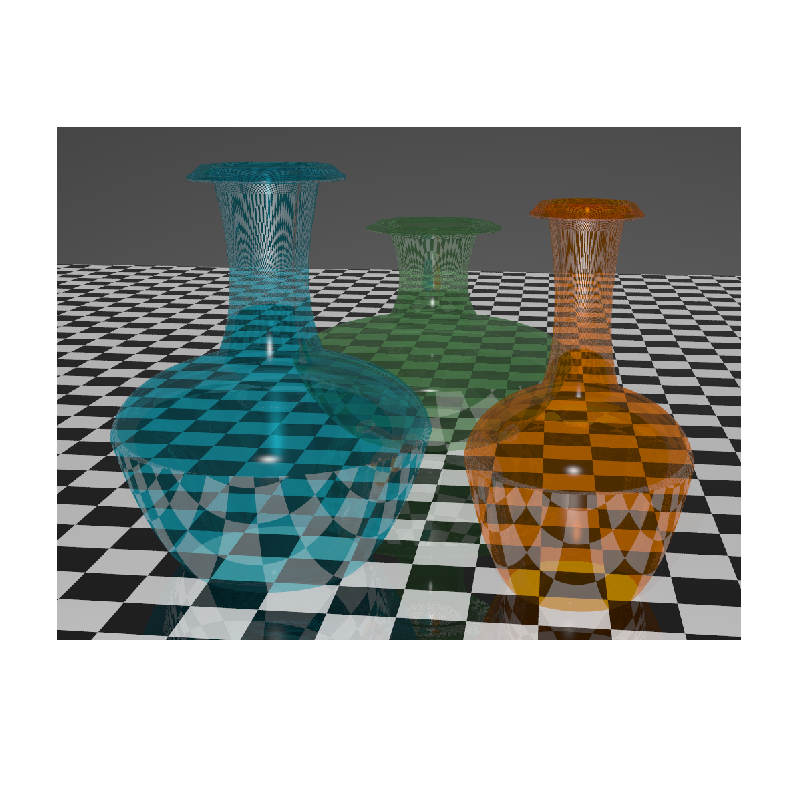

img = pl.render();
imshow(img);

####  Elapsed time

toc

Elapsed time is 46.311673 seconds.
